% GPIB Test Suite
% Uwe Rother

clc;
close all;
clearvars -except runcounter measData
delete(visadevfind());

### Manage some persistent variables

for comparison of ongoing measurements

if exist('runcounter') == 1
    runcounter = runcounter + 1;
else
    runcounter = 1;
    measData = {};
end




## Init of HP4192A

% use of short name "d" for device
d = visadev("GPIB0::1::INSTR");
% d.EOIMode = "off";
d.Timeout = 1;
writeline(d,'D0');
writeline(d,'T2');
[tf,statusByte] = visastatus(d);
s = "";
s = sprintf('Status %d',dec2hex(statusByte));
disp(s);

Status 52Status 50




%sweep auto
writeline(d, 'A3B3');       % Aktiviert DISPLAY A und DISPLAY B als Phase / Winkel
writeline(d, 'T2');         % Trigger ext
writeline(d, 'F1');         % Ausgabe im erweiterten Modus (A/B Daten mit Einheiten)
writeline(d, 'D0');           % Data Ready off

% Frequenzparameter setzen
% Frequenzparameter setzen mit korrektem Format
writeline(d, 'TF5.00EN');     % Startfrequenz: 1 kHz
writeline(d, 'PF200.00EN');     % Stopfrequenz: 1 MHz
writeline(d, 'SF5.00EN');     % Schrittweite: 10 kHz
writeline(d, 'FR5.00EN');
ftab = transpose(5000:5000:200000);
ftab = ftab ./ 1000;
[l,~] = size(ftab);

writeline(d,'W0');          % sweep Man
writeline(d,'D1');           % Data Ready on
pause(0.5);
[tf,statusByte] = visastatus(d);
pause(0.5);

f = ftab;
L = zeros(l,1);
Q = zeros(l,1);
sweep = struct('f',f,'L',L,'Q',Q);

% Grafik erstellen
h= figure;
grid on;
hold on;
set(gcf,'Visible','on');
yyaxis left;
p1 = plot(sweep.f,sweep.L,'XDataSource','sweep.f','YDataSource','sweep.L');
%p1.XDataSource = sweep.f;
%p1.YDataSource = 'sweep.L';
xlabel('f/kHz');
ylabel('L/uH');
ylim([0 25]);
yyaxis right;
p2 = plot(sweep.f,sweep.Q,'XDataSource','sweep.f','YDataSource','sweep.Q');
%p2.XDataSource = 'sweep.f';
%p2.YDataSource = 'sweep.Q';
ylabel('R/Ohm');
linkdata on;

title('LundB Spule');
% Y-Achse skalieren
% ylim([-1 5]);
xlim([0 ftab(end)]);

sweep.f = f;
for j=1:l
    disp('----------');
    disp('Trigger');
    writeline(d,'R3');
    writeline(d,'EX');
    pause(0.25000);

    while true
        disp('check statusbyte');
        statusByte = 255;
        [tf,statusByte] = visastatus(d);
        pause(0.1);
        disp(dec2hex(statusByte));
        isSweepActive = bitget(statusByte, 5,"uint8");
        measReady = bitget(statusByte,1,"uint8");
        if measReady
            disp('measurement ready');
            break;
        else
            disp('wait for measurement');
            disp(i);
        end      
    end
    x = readline(d);
    y = x.split();
    A = str2double(extractAfter(y(1),4));
    B = str2double(extractAfter(y(2),4));
    C = str2double(extractAfter(y(3),4));
    disp(A);
    disp(B);
    sweep.L(j) = A*1e6;
    sweep.Q(j) = B;
    refreshdata(p1);
    refreshdata(p2);
    if(~isSweepActive) 
       % break;
    end
    writeline(d,'W2');

    disp('loop on')
end

----------


Trigger


check statusbyte


41


measurement ready


   2.3000e-05



    0.3400



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2500e-05



    0.3500



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2400e-05



    0.3700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2400e-05



    0.3900



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2300e-05



    0.4100



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2300e-05



    0.4500



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2200e-05



    0.4800



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2200e-05



    0.5200



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2200e-05



    0.5700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2100e-05



    0.6200



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2100e-05



    0.6800



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2100e-05



    0.7400



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.2000e-05



    0.8000



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1970e-05



    0.8700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1930e-05



    0.9300



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1880e-05



    1.0100



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1830e-05



    1.0900



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1780e-05



    1.1700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1730e-05



    1.2500



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1690e-05



    1.3300



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1630e-05



    1.4200



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1580e-05



    1.5000



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1530e-05



    1.5900



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1470e-05



    1.6800



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1420e-05



    1.7700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1370e-05



    1.8700



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1310e-05



    1.9600



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1260e-05



    2.0500



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1200e-05



    2.1500



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1150e-05



    2.2400



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1100e-05



    2.3400



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.1050e-05



    2.4300



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0990e-05



    2.5300



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0940e-05



    2.6300



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0890e-05



    2.7200



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0840e-05



    2.8200



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0790e-05



    2.9100



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0740e-05



    3.0100



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0690e-05



    3.1000



loop on


----------


Trigger


check statusbyte


41


measurement ready


   2.0640e-05



    3.2000



loop on


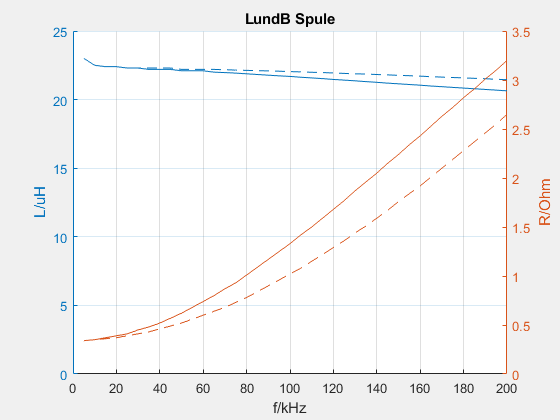


measData{runcounter} = sweep;

if(runcounter > 1)
    lastplot = measData{runcounter-1};
    yyaxis left;
    plot(lastplot.f,lastplot.L);
    yyaxis right;
    plot(lastplot.f,lastplot.Q);
end